# Example 3 from Session on Inverse Z-Transform

PFE for a z-transfer function when there are complex poles.

Prepared for EG-247 Signals and Systems by Dr Chris P. Jobling

## Problem

Use the partial fraction expansion to compute the inverse z-transform of


$$F(z) = \frac{z + 1}{(z-1)(z^2 + 2z + 2)}$$


## Solution

syms z n
Fz = (z + 1)/((z - 1)*(z^2 + 2*z + 2))

$$Fz = \frac{z+1}{\left(z-1\right)\,\left(z^{2}+2\,z+2\right)}$$

fn = iztrans(Fz)

$$fn = \frac{0.4000\,{\left(-1\right)}^{n}\,2^{n}\,\cos\left(0.7854\,n\right)}{2^{0.5000\,n}}-0.5000\,\delta_{n,0}+0.4000+0.3000\,{\left(-1\right)}^{n}\,{\left(1-1\,\mathrm{i}\right)}^{n-1}\,\mathrm{i}-0.3000\,{\left(-1\right)}^{n}\,{\left(1+1\,\mathrm{i}\right)}^{n-1}\,\mathrm{i}$$

pretty(fn)

    n     1      n                            n         n - 1               n
(-1)  --------- 2  cos(0.7854 n) 0.4000 + (-1)  (1 - 1i)      0.3000i - (-1)
       0.5000 n
      2

           n - 1
   (1 + 1i)      0.3000i - 0.5000 kroneckerDelta(n, 0) + 0.4000



iztrans(fn)

$$ans = 0.4000\,\delta_{k,0}-0.5000\,\mathrm{iztrans}\left(\delta_{n,0},n,k\right)+0.4000\,\mathrm{iztrans}\left(\frac{{\left(-1\right)}^{n}\,2^{n}\,\cos\left(0.7854\,n\right)}{2^{0.5000\,n}},n,k\right)+0.3000\,\mathrm{iztrans}\left({\left(-1\right)}^{n}\,{\left(1-1\,\mathrm{i}\right)}^{n-1},n,k\right)\,\mathrm{i}-0.3000\,\mathrm{iztrans}\left({\left(-1\right)}^{n}\,{\left(1+1\,\mathrm{i}\right)}^{n-1},n,k\right)\,\mathrm{i}$$

Fz = simplify(Fz)

$$Fz = \frac{z+1}{z^{3}+z^{2}-2}$$

% inverse z-transform

## Plot Sequence

den = sym2poly(collect((z - 1)*(z^2 + 2*z + 2)));
num = [1, 1];
n = 1:15;
fn = dimpulse(num,den,20);

## Plot

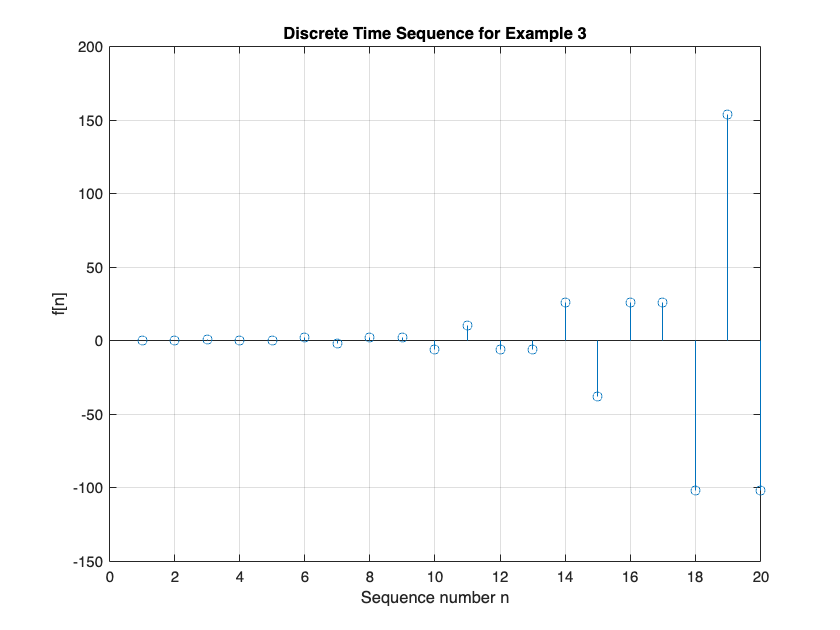

stem(fn),grid
title('Discrete Time Sequence for Example 3');
ylabel('f[n]')
xlabel('Sequence number n')

## Also plots impulse response

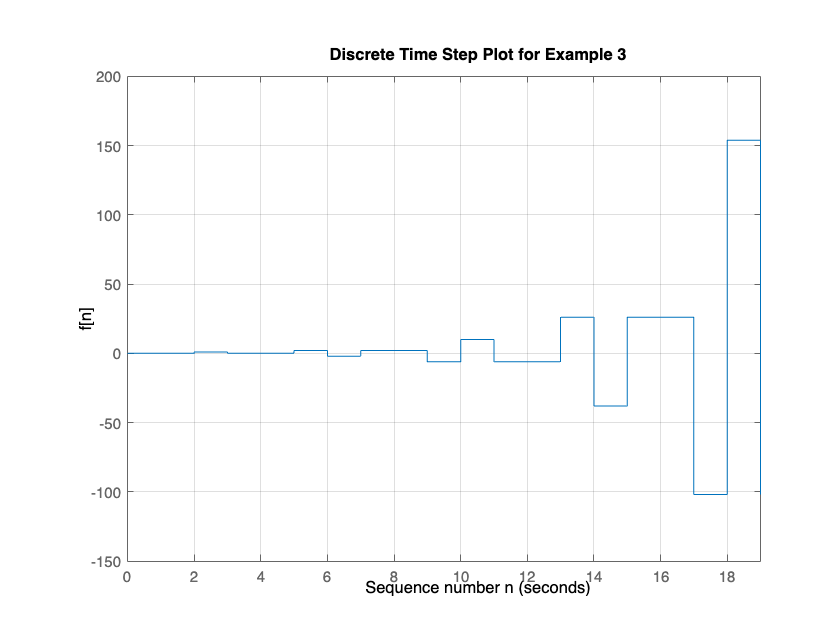

dimpulse(num,den,20), grid
title('Discrete Time Step Plot for Example 3');
ylabel('f[n]')
xlabel('Sequence number n')